#                                        

# **Writing Data Analysis Programs with Matlab**

# Introduction

### Learning Outcomes

- Manipulate data sets using Matrices, Tables, Cell Arrays and Structure

- Import data into matlab

- Write simple data analysis programs

- Use data analysis functions e.g. regression analysis, classification and clustering

- Basic data visualisation 

### Sections

- Preliminary

- Importing Data

- Import Data from Single File Containing Heterogeneous Data

- Basic Statistics

- Regression Analysis

- Diagnostic Plots

- Classification Using Discrimininant Analysis

- Text Processing

Data visualisation is one of the first and most powerful methods we employ for gaining insights into data. Further methods are classification and cluster analysis methods which are applicable to categorical data. Matlab also provides tools for analysing text data. A common task in data analysis is to understand and determine the relationships within data sets,  this is challenging and there are numerous techniques. These techniques form a basis for techniques such as optimisation, machine learning and deep learning all of which are supported within Matlab.

In this introductory Matlab session we will review a number of techniques such as regression analysis, classification and text processing. The research cycle is a collaboration of project partners turning ideas into project proposals after execution of the research process results are disseminated through the publication and sharing of research outputs.

The research process is an acquisition of data presenting that as information after analysis insight and sharing this knowledge becomes a shared wisdom. 

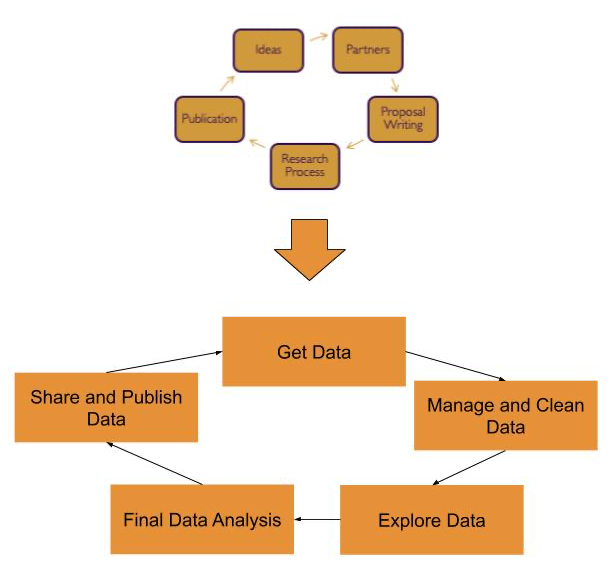

To understand the research data lifecycle, we will use a number of data sets. 

# Preliminaries

### Matlab 

MatLab is the matrix laboratory providing tools for analysing and visualisation of data. Users of matlab need an understanding of how to manipulate and manage data.

The basic techniques for manipulating matrices are revised in the livescript matlab_fundamentals.mlx

%x= % 1x3 row vector elements separated with spaces
x=[1 2 3]

x =      1     2     3


%y=[] %2x1 matrix  column vector elements separated by ;
y=[sqrt(10); pi^2; sin(pi/4)]

y =     3.1623
    9.8696
    0.7071


%z=[]  % 2x3 matrix
z=[4 5 6; 7 8 9]

z =      4     5     6
     7     8     9


Functions to define array using linspace and the colon notation

u=zeros(2,2);
v=eye(3,3);
w=ones(4,4);
x1=linspace(1,10,5);  % linspace(first,last,number of elements)
y1=(1:1:10);
y1t=(1:1:10)'; %transpose operation
z1=rand(5,1);
 

 
 

First create a 6x4 matrix of random numbers.

data=100*rand(6,4)

data =    31.8778    2.9220   45.8849   62.4060
   42.4167   92.8854   96.3089   67.9136
   50.7858   73.0331   54.6806   39.5515
    8.5516   48.8609   52.1136   36.7437
   26.2482   57.8525   23.1594   98.7982
   80.1015   23.7284   48.8898    3.7739



%x1= %extract  a specific element
x1=data(2,2)

x1 = 92.8854

# Importing Data

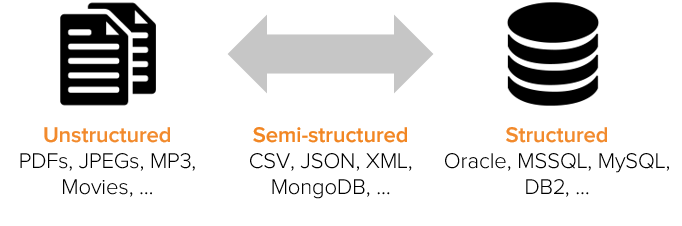

Matlab provides a range of tools for importing a variety of formats including text, spreadsheets, images, audio files, xml formats and general pupose tools for developing bespoke file readers.

One of the first methods is the save and load command which can be used to save and load workspace variables.

For example to save all the current work space variables use the command

%TODO
save('workspacevars.mat')

to save a specific variable for example the M cell array

%TODO
%save the data matrix
save('workspace-data.mat',"data")

Note variables to be saved are indicated in single quotes and there is a comma separated list of variables.

[Data Import and Export](https://uk.mathworks.com/help/matlab/data-import-and-export.html)

The simplest way to import data is to use the data import wizard provided through the matlab workbench there is a button to start the wizard on the home bar of the Matlab workbench. When the wizard starts the user is presented with a file input dialog, the dialog which follows presents a section of the input file and allows the user to set separators between each of the fields, set the number of headerlines. Data can be read in directly using the importdata command. A useful feature of the data import wizard is the script generation utility for generating a script used to import the data file. 

[importdata](https://uk.mathworks.com/help/matlab/ref/importdata.html)

# Import data from a single file containing heterogeneous data.

Initially,  we will work with an anonymised biomedical data set from the  2007-2008 US National Health Survey.  We will use a table to hold the results. Tables are for storing heterogeneous tabular data.

% Inspect the data file:
%first modify the path variable so that data files can be located
addpath('../data/');

%Open a data file using the editor and inspect it
edit('MedicalData.txt'); 

 

Use READTABLE to import the data. If unfamiliar with this function, this  is a good opportunity to demonstrate the use of F1/searching in the documentation. It's also worth mentioning the table of import/export functions at this point. Search for "Supported File Formats" to bring up this table in the documentation, and point out the use of the READTABLE function.

%help('readtable');

%TODO
%use readtable specify tab Delimeter '\t' write data to medData
medData = readtable('MedicalData.txt','Delimiter','\t') 

medData = 5610×21 table
    IDNum     Sex     Age     Ethnicity      Pulse    BPSyst1    BPDias1    Height    Weight     BMI     LegLength    ArmLength    ArmCirc    Waist    Triceps    Subscapular    ReportHeight    ReportWeight    Overweight    LikeToWeigh         BMIClass     
    _____    _____    ___    ____________    _____    _______    _______    ______    ______    _____    _________    _________    _______   

Why are people so old? They're not really, it's just that Age is recorded in months. So we might want to convert the data.


% Table variables are accessed using the dot syntax (similar to structures).
medData.Age = medData.Age/12; % Note: age is recorded in months.

% Best practice would be to have comments explaining any "magic numbers" in
% the code. For example, where did the 12 come from?
% As an alternative, we could use "self-commenting" variables, e.g.
months2years = 1/12;

% Compute pulse pressure and store this as an additional table variable.
medData.BPDiff = medData.BPSyst1-medData.BPDias1;

% What about naming conventions? Generally we would use camel case.
% Table/structure variable names can be capitalised. Try to 
% agree on a convention, and then stick with it.

### Plotting vectors and annotating graphs.

How  can we visualise the information we have just computed? It's worth  showing all available plots from the Plots tab at this point.

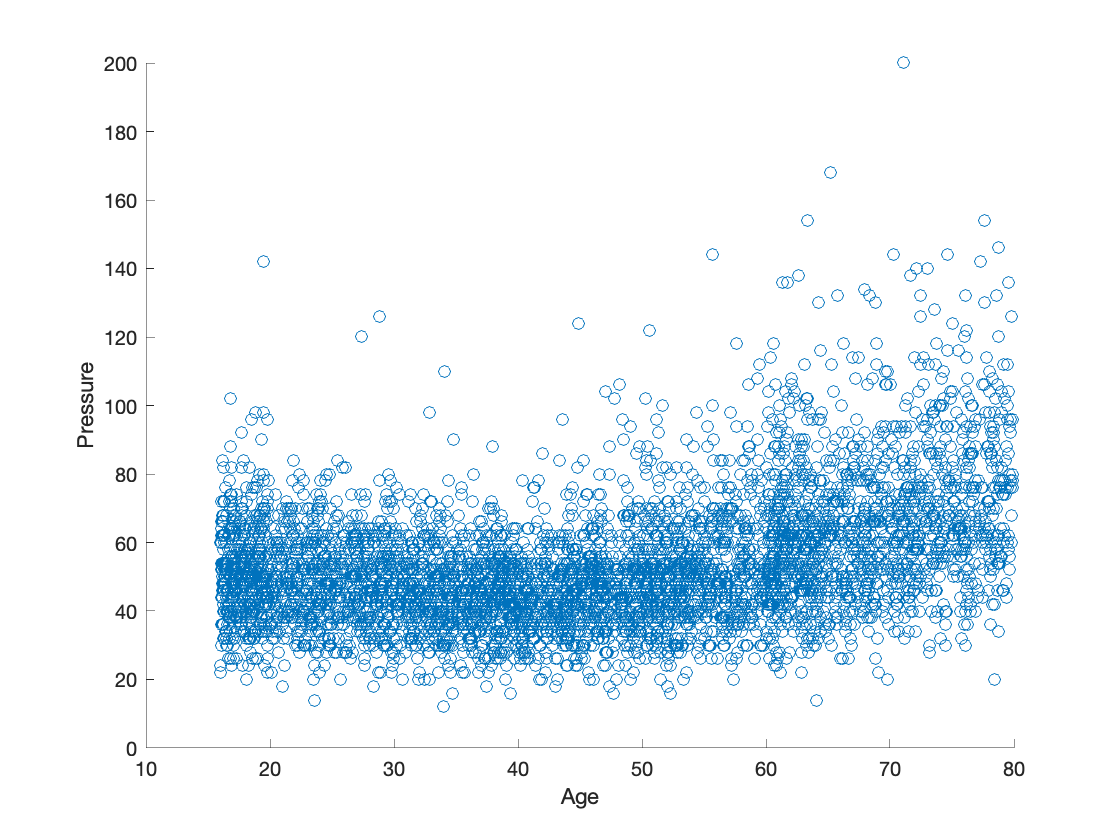

figure % New figure.
%TODO
% Basic discrete plot and annotations.
%scatter plot medData.Age v medData.BPDiff xlabel age ylabel pressure
scatter(medData.Age,medData.BPDiff)
xlabel('Age')
ylabel('Pressure')

### Low-Level File I/O.

Suppose we have data from a file containing numeric data. How can we read this in efficiently?  Three-step process, using textscan for text files.

% The open/close statements are essential. 
% What happens if the file remains open? Why is it good practice to ensure files are
% closed after use?

clf
fileID = fopen('HeightWaistData.txt');

% The next step is critical. This is where you can control the precise
% format MATLAB will use to import the data. See the documentation for
% textscan for more details.
dataFormat = '%f %f'; % Two columns of numeric (double, floating point) data.
heightWaistData = textscan(fileID, dataFormat, ...
    'Headerlines', 1, 'Delimiter', '\t');

fclose(fileID);

% Do we really need to use DOUBLE to store the data? How
% many significant figures are there? What else could we use to save
% memory? (SINGLE, specified via %f32 in TEXTSCAN).

### Cell Arrays.

The data from textscan is  imported as a cell array in the MATLAB workspace. The data is imported  into a 1x2 cell array (each column of data is stored in a separate  cell). A useful visualisation function for inspecting cell arrays is  CELLPLOT. This can help to alleviate misunderstanding of how cell arrays work.

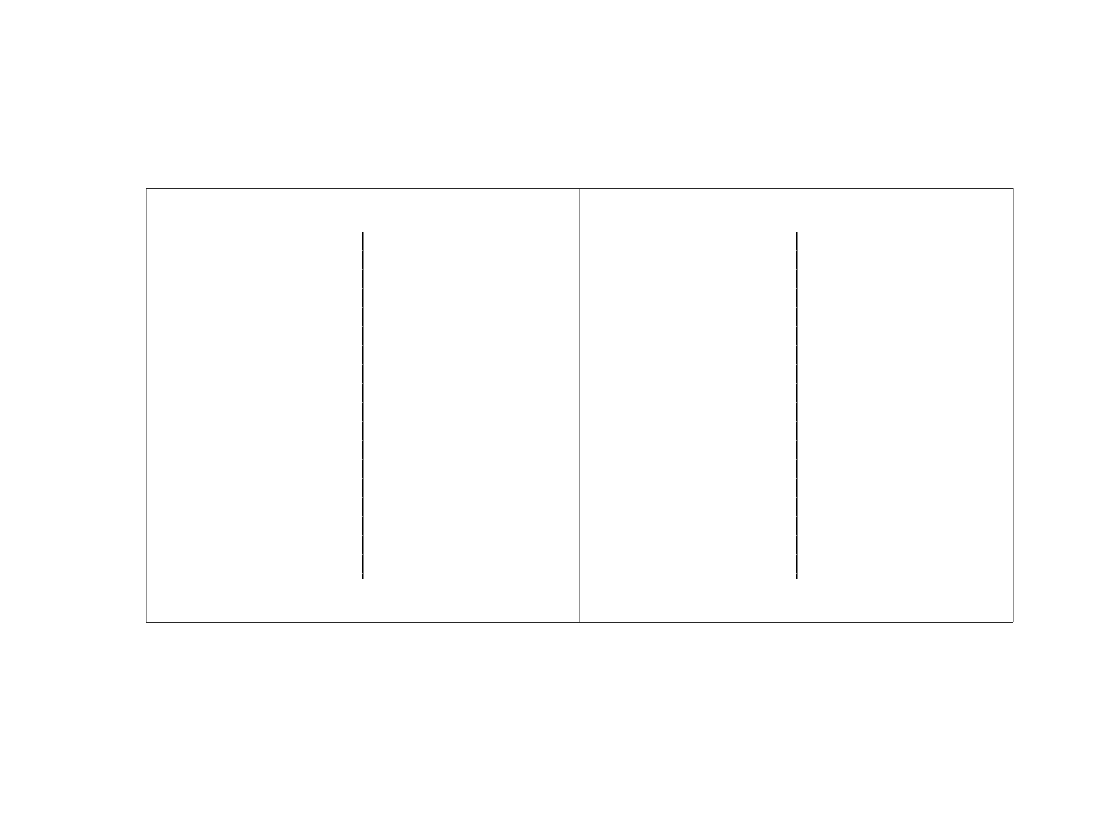

figure; cellplot(heightWaistData)

### Converting Data Types.

All the elements of a MATLAB array must be the same type. This rule is particularly important when attempting to concatenate data of different types (e.g. strings  and numbers). 

An ETL pipeline is a sequence of processes for obtaining data and transforming into a valid form for data analysis

Extract -> Transform->Load

Unwanted Observations

Remove Outliers

Fix Structural Errors

Handle Missing Data

Filter and Sort data

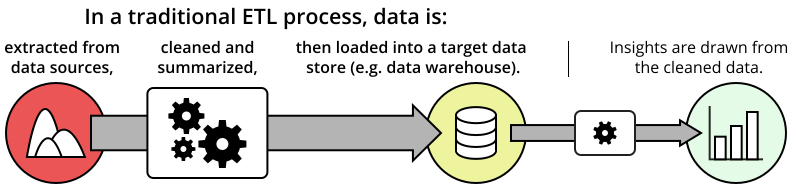

% Convert the data to a useful format.
HW = cell2mat(heightWaistData);

% Alternatively, you can show HW = [heightWaistData{1}, heightWaistData{2}]
% or even HW = [heightWaistData{:}]. However, this will requires
% understanding of cell indexing (curly brackets give contents) versus standard 
% array indexing (round brackets give a sub-cell array).

% Try computing the mean of each variable.
%disp(mean(HW))

% Why does this not give us "proper" values? NaNs - missing data. We would
% like to remove them to obtain proper results. However, we need to know
% how to index into arrays before attempting this.

### Accessing Data in Arrays.

Data in MATLAB can be accessed using several indexing methods. Generally, row/column, or  subscript, indexing is the natural method which follows naturally. Useful  tips include the use of the "end" keyword, as well as the use of  the colon as an index as a shortcut for 1:end. The row/column indices do not have to be scalar values.

% Extract height and waist data separately.
Height = HW(:, 1);
Waist = HW(:, 2);

### Dealing with Missing Data.

This requires use of logical indexing (passing logical arrays as indices to other  arrays). The key function here is ISNAN (see the  reference page IS* in the documentation which has a list of all useful  functions for detecting certain conditions or states). Also, search the reference page operators which has a list of all  MATLAB's operators, including logical operators which are required here.

% Remove any observations containing NaNs.
badObs = isnan(Height) | isnan(Waist);
cleanHWData = HW(~badObs, :);
%disp(mean(cleanHWData))

## Importing Data from Multiple Files.

We have  seen how to import homogeneous and heterogeneous data from single files. Often, researchers have multiple data files with similar formats, so it is useful to know how to batch process a list of files. The  documentation contains a list of functions for performing file and  directory management, such as changing directory, moving files, and  creating directories: MATLAB -> Data and File Management -> File  Operations -> Files and Folders.

% The first step is to form a list of files to import data from.
% Warning: be careful here to avoid platform-dependent issues. Use of
% FILESEP is generally recommended to avoid hard-coding slashes or
% backslashes. This should recover a list of .txt files in the "ArmsLegs"
% directory.
fileInfo = dir(['../data/ArmsLegs', filesep, '*.txt'])

fileInfo = 10×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


fileList = {fileInfo.name}

fileList = 1×10 cell array
    {'ArmsLegs_01.txt'}    {'ArmsLegs_02.txt'}    {'ArmsLegs_03.txt'}    {'ArmsLegs_04.txt'}    {'ArmsLegs_05.txt'}    {'ArmsLegs_06.txt'}    {'ArmsLegs_07.txt'}    {'ArmsLegs_08.txt'}    {'ArmsLegs_09.txt'}    {'ArmsLegs_10.txt'}


Here, we need to  operate on each data file. We know how many data files there are, so a  for-loop is appropriate. Use ISKEYWORD to display a list of MATLAB's  programming keywords. You may want to mention other common constructs  such as if-elseif-else, try-catch, switch-case and while-loops.

## Structure Arrays.

We would like to store the name of each file (a string) as well as the  numerical data it contains (a matrix with three columns) together in the same variable. Tables are not suitable for this, because in a table all variables must have the same number of observations. We can use a  structure array instead. This allows access to the data using the same  convenient dot syntax we used for tables, but also allows storage of  mixed-size data. (However, structures have far less available  functionality associated with them than tables. For example, SORTROWS  comes with tables but not with structures.)

% Using the debugger we can show that the loop is performed sequentially. We may also
% run the code using the Code Analyzer. This leads to the idea of preallocation, which can be shown
% explicitly using the STRUCT function, for example. Sometimes,
% it's much easier just to do the loop backwards and therefore have the
% preallocation performed implicitly.
for k = numel(fileList):-1:1
    ArmsLegs(k).FileName = fileList{k};
    ArmsLegs(k).Data = dlmread(['../data/ArmsLegs',filesep,fileList{k}], '\t', 1, 0);
end

## Concatenation.

After reading all the data,  we would like to merge it into one variable so that we have all of the  body measurements together. It's worth spending a bit of time talking  about concatenation with square brackets [], and then mention that for  comma-separated lists, you can use VERTCAT, HORZCAT and CAT.

ALData = vertcat(ArmsLegs.Data);

## Logical Indexing.

We have seen logical  indexing above. We used it to detect and remove missing values. It is an important and widely applicable MATLAB language feature. For example,  we might want to visualise the split/separation between two different  groups in our population, e.g. males and females.

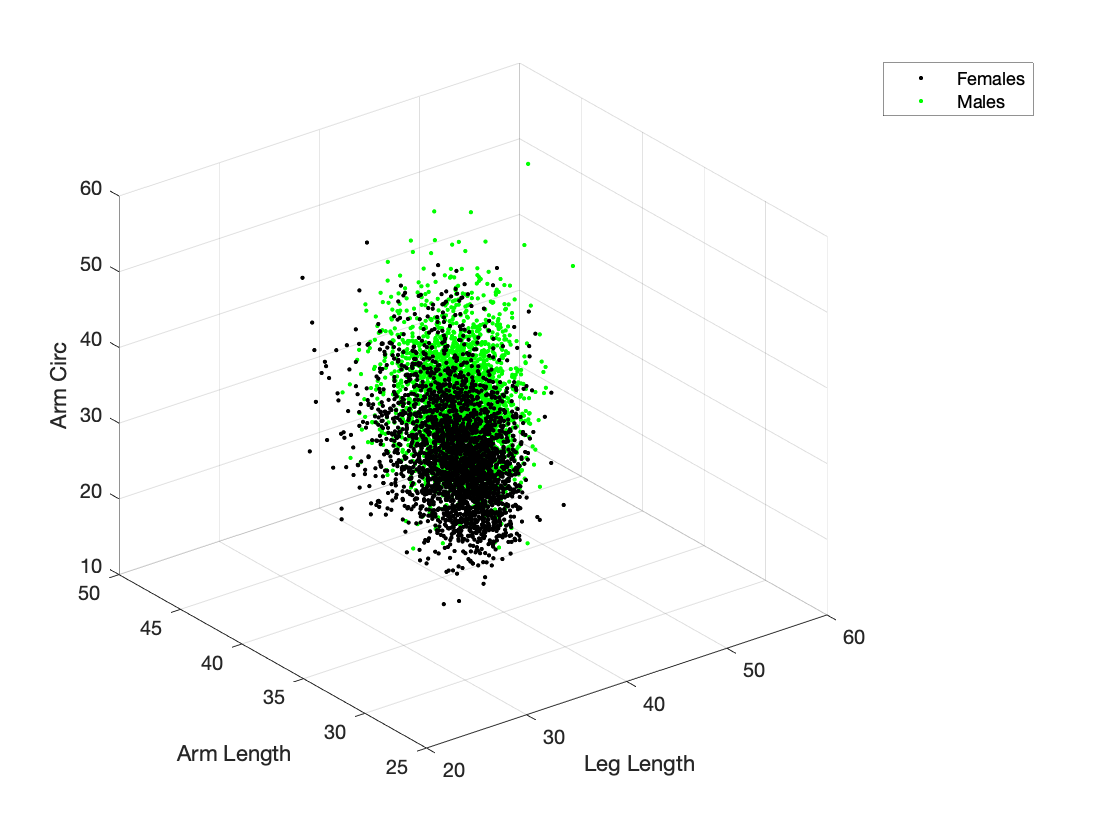

females = strcmp(medData.Sex, 'F');
figure
scatter3(ALData(females, 1), ALData(females, 2), ALData(females, 3), 'k.')
hold on % Ask what happens if we don't use HOLD here.
scatter3(ALData(~females, 1), ALData(~females, 2), ALData(~females, 3), 'g.')
hold off
xlabel('Leg Length')
ylabel('Arm Length')
zlabel('Arm Circ')
legend('Females', 'Males')

## Saving and Loading MAT-Files.

We have spent a lot of time and effort into importing our data effectively. Do we  really want to repeat this effort if we need the data again? Probably  not. You can save all the data to disk using a MAT-file (designed to  hold MATLAB data and variables). Loading from MAT-files is also faster  in general terms than running file import code. The idea is to import  the data only once, and then save it to a MAT-file for future use or  distribution to others.

% Save data to a MAT-file.
save('S01_HealthData.mat')

# Basic Statistics

After loading a dataset and undertaking some preliminary filtering, the first stage of analysis might be an inspection of the raw data. There are further steps that we can take such as a visualisation of the distribution of the data and the computation statistical measures such as the  mean, maxima, minima, median, variance and deviations.

To illustrate this, consider the car data set extracted from the 1974 *Motor Trend* US magazine, and comprises fuel consumption and 10 aspects of automobile design and performance for 32 automobiles (1973–74 models). Each column of the data table  represents the following properties.

clf
data=readtable('../data/mtcars.csv')

data = 32×12 table
             Var1              mpg     cyl    disp     hp     drat     wt      qsec     vs    am    gear    carb
    _______________________    ____    ___    _____    ___    ____    _____    _____    __    __    ____    ____

    {'Mazda RX4'          }      21     6       160    110     3.9     2.62    16.46    0     1      4       4  
    {'Mazda RX4 Wag'      }      21     6       160    110     3.9    2.875    17.02    0     1      4       4  
    {'Datsun 710'         }    22.8     4       108     93    3.85     2.32    18.61    1     1      4       1  
    {'H

Each column of the table has the following meaning

mpg, Miles/(US) gallon;

cyl, Number of cylinders;

disp, Displacement (cu.in.);

hp, Gross horsepower;

drat, Rear axle ratio;

wt, Weight (1000 lbs);

qsec, 1/4 mile time;

vs, Engine (0 = V-shaped, 1 = straight);

am, Transmission (0 = automatic, 1 = manual);

gear, Number of forward gears;

carb, Number of carburretors.

After a visual inspection of the raw data one of the first things we can do is to use plots such as histograms and scatter plots. Here we use the subplot command to create an array of plots.

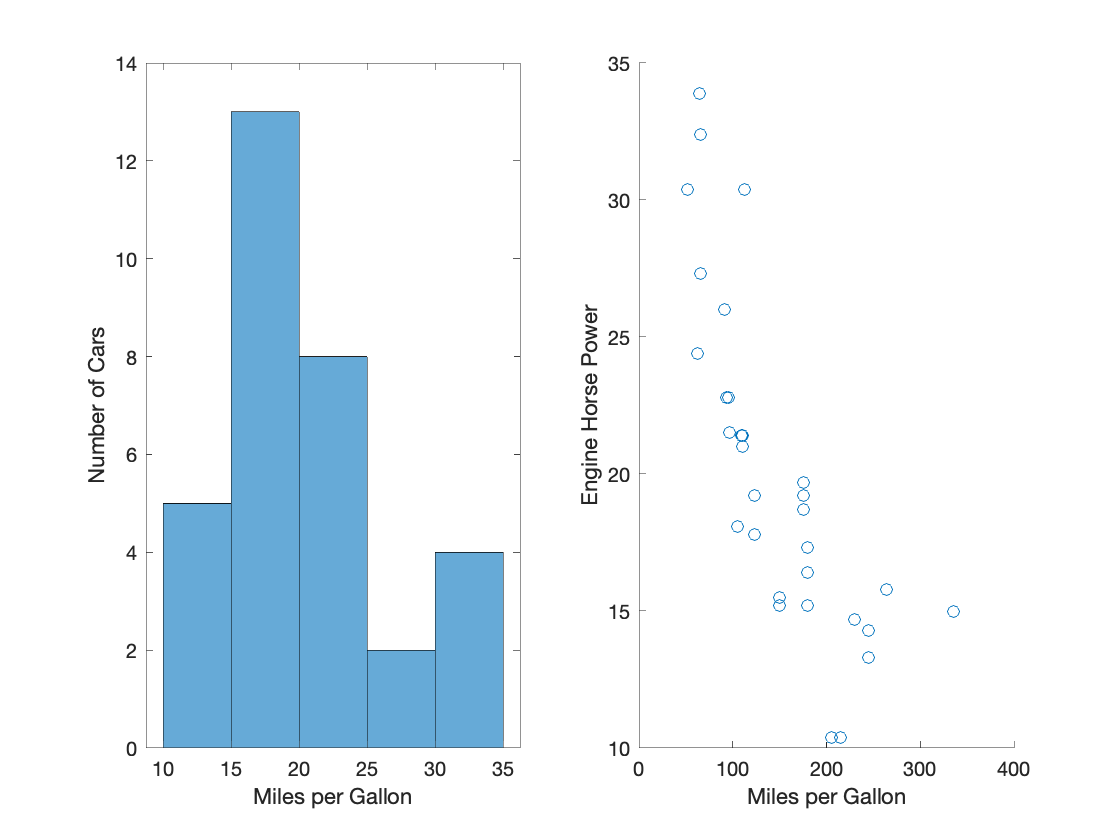

subplot(1,2,1)
histogram(data.mpg)
xlabel('Miles per Gallon');
ylabel('Number of Cars');
subplot(1,2,2)
scatter(data.hp,data.mpg)
xlabel('Miles per Gallon');
ylabel('Engine Horse Power');

We also use statistical measures such as mean, median and mode.

- mean  - the average value of a set of numbers

- median - the middle value of a set of numbers

- mode   -  the most commonly occuring value

The histogram plot clearly verifies the modal value and the sorted table helps us to verify the median value.  As  mentioned at the start we need to undertake a fair amount of preparation or wrangling of our data before we complete our analysis.

%sum of the series
sum(data.mpg)

ans = 642.9000

%mean of the data
mean(data.mpg)

ans = 20.0906

%median data value
median(data.mpg)

ans = 19.2000

%sort the data in order
sort(data.mpg)

ans =    10.4000
   10.4000
   13.3000
   14.3000
   14.7000
   15.0000
   15.2000
   15.2000
   15.5000
   15.8000


%most frequent vaule in the array
mode(data.mpg)

ans = 10.4000

To other properties which we shall use are the variance and the standard deviation.

%standard deviation
std(data.mpg)

ans = 6.0269

%variance
var(data.mpg)

ans = 36.3241

The standard deviation describes the spread of values if the standard deviation is small then the values are close to the mean value otherwise a large standard deviation indicates a larger spread about the mean. Multiplying the standard deviation by itself gives another measure of spread known as the variance.

# Regression Analysis

Working with datasets we want to use that data to predict  and determine the response of data to a combination of one or more variables. Regression analysis is a statistical method allowing us to model the relationships between one or more variables. In this sense we use regression analysis to make predictions about real world data. There are many forms of regression  including simple linear regression, multiple linear regression and logistic regression. Here we consider the case of linear regression.

In a linear model, if the errors belong to a normal distribution the least squares estimators are also the maximum likelihood estimators.

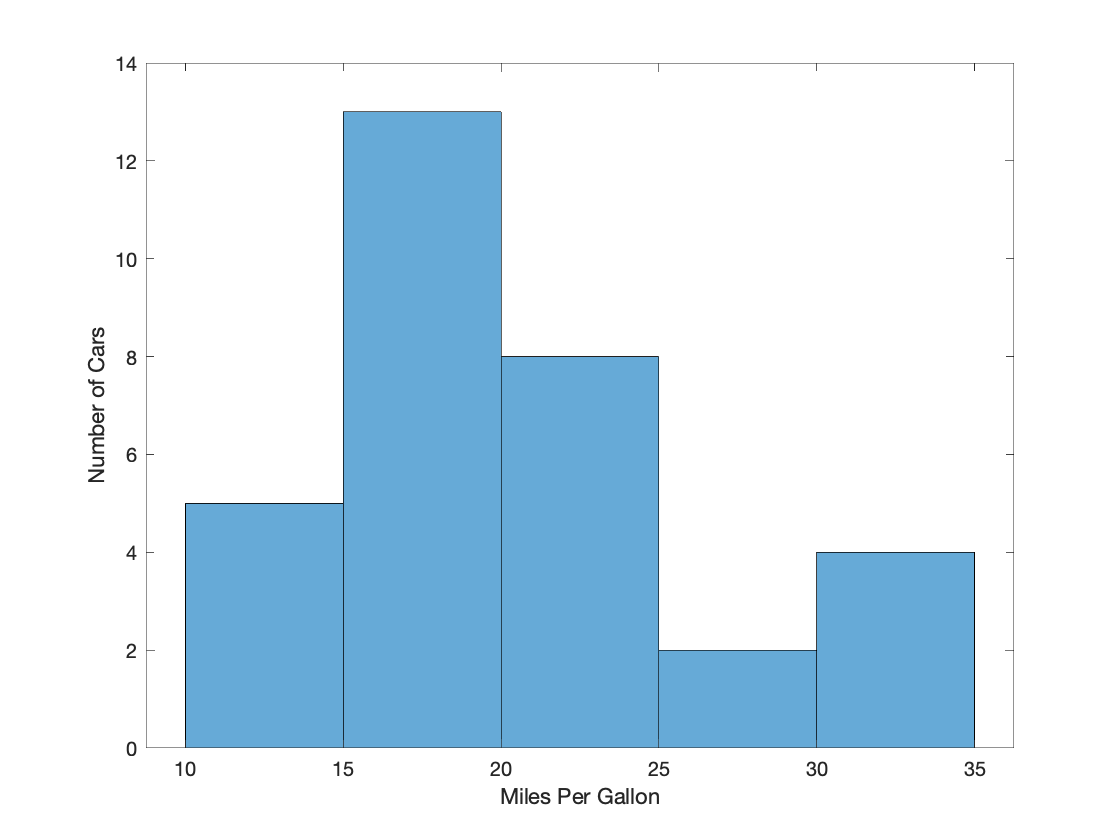

clf

histogram(data.mpg)
xlabel('Miles Per Gallon');
ylabel('Number of Cars');

When considering the relationship between the arrays in a dataset it is necessary to consider what kind of distribution the data follows.

- Normal distribution describes continuous data which have a symmetric distribution, with a characteristic 'bell' shape.

- Binomial distribution describes the distribution of binary data from a finite sample. Thus it gives the probability of getting r events out of n trials.

- Poisson distribution describes the distribution of binary data from an infinite sample. Thus it gives the probability of getting r events in a population.

Other statistical distributions to consider are the t distribution and the chi squared distribution.

Matlab provides functions which are useful for investigatin distributions. The fitdist function returns the probability distribution for a data set for a specified type of distribution it returns the mean and the standard deviation for the distribution. The pdf function can be used to generate the probability distribution  using the distribution data produced by the fitdist function.

Now use the fitdist function to determine if our car modelling data follows a normal distribution.

pdmpg = fitdist(data.mpg,'Normal')

pdmpg =   NormalDistribution

  Normal distribution
       mu = 20.0906   [17.9177, 22.2636]
    sigma = 6.02695   [4.83182, 8.0127]


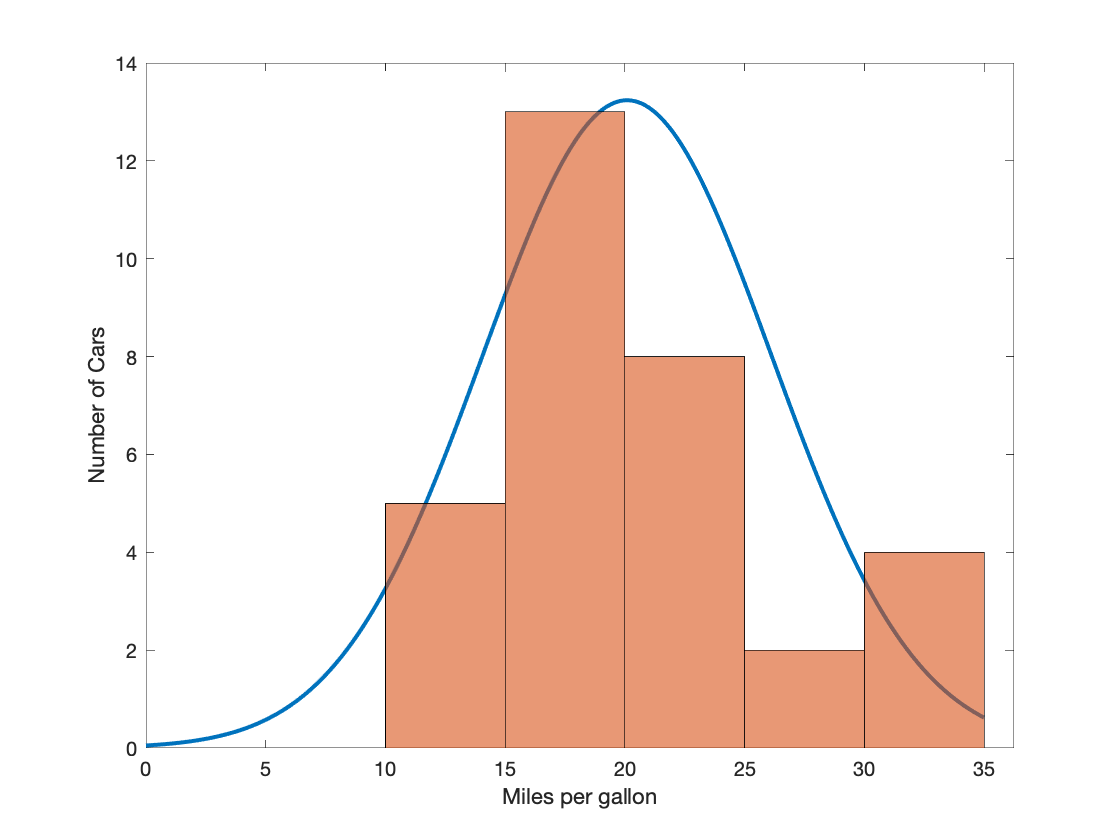

clf
x_values = 0:0.05:35;
y = 1400*pdf(pdmpg,x_values)/7;
plot(x_values,y,'LineWidth',2)
hold on
histogram(data.mpg)
xlabel('Miles per gallon')
ylabel('Number of Cars')
hold off

In this example we want to consider how the miles per gallon for a car changes with the size of the engine. Using Matlab some methods we can use to fit a model to data are as follows:

- [Least-Squares Fit](https://localhost:31515/static/help/stats/linear-regression-model-workflow.html#btcpwno)

- [Robust Fit](https://localhost:31515/static/help/stats/linear-regression-model-workflow.html#btcpwmd)

- [Stepwise Fit](https://localhost:31515/static/help/stats/linear-regression-model-workflow.html#btcpwm_)

%For example, to model our car data we use the following:
yv=data.mpg;
xv=data.disp;
tbl = table(yv,xv);
mdl = fitlm(tbl,'linear');

In addition to the fitlm utility for  linear regression Matlab also includes the nlinfit function for non linear regression. Also provided are a range of tool for analysing the results of regression analysis. Having used our data set to train the system we want to understand how reliable the result of that regression. We can use functions such as the plotDiagnostics function.

In this section we detail some of the steps for performing a linea regression using the method known as the, Least squares method. In this method we attempt to minimise the sume of the squares of the differences between the observed values and the values predicted by the results of the regression. To use the method  we need to compute the following quantities.

Sample mean


$$\bar{y} = \frac{1}{n}\sum_{i=1}^n y_i$$


Standard deviation


$$\sigma = \sqrt\frac{\sum\limits_{i=1}^{n}(y_i – \bar{y})^2} {n – 1}$$


The regression coefficient


$$$\hat{\beta}_1 = \frac{\sum(x_i – \bar{x}) (y_i – \bar{y})} {\sum(x_i – \bar{x})^2}$$$


Mathworld at wolfram.com provide a helpful description of the method

[http://mathworld.wolfram.com/LeastSquaresFitting.html](http://mathworld.wolfram.com/LeastSquaresFitting.html)


num=numel(xv);

%mean values of the variable and the response
xmean=mean(xv);
ymean=mean(yv);

%sum of the variable and the response and the sum of the squares of the
%values
sxx=sum(xv.*xv);
syy=sum(yv.*yv);
sx=sum(xv);
sy=sum(yv);

ssxx=sum((xv-xmean).*(xv-xmean)); %sum of the square differences between the variable and the mean variable
ssyy=sum((yv-ymean).*(yv-ymean)); %sum of the square differences between the response and the mean response

ssxy=sum((xv-xmean).*(yv-ymean));

b=ssxy/ssxx;       %Model parameter - gradient of the linear relationship

a=ymean-b*xmean;   %Model parameter - constant for a linear relationship

corcoeff=ssxy.^2/(ssxx*ssyy);  %The correlation coefficient

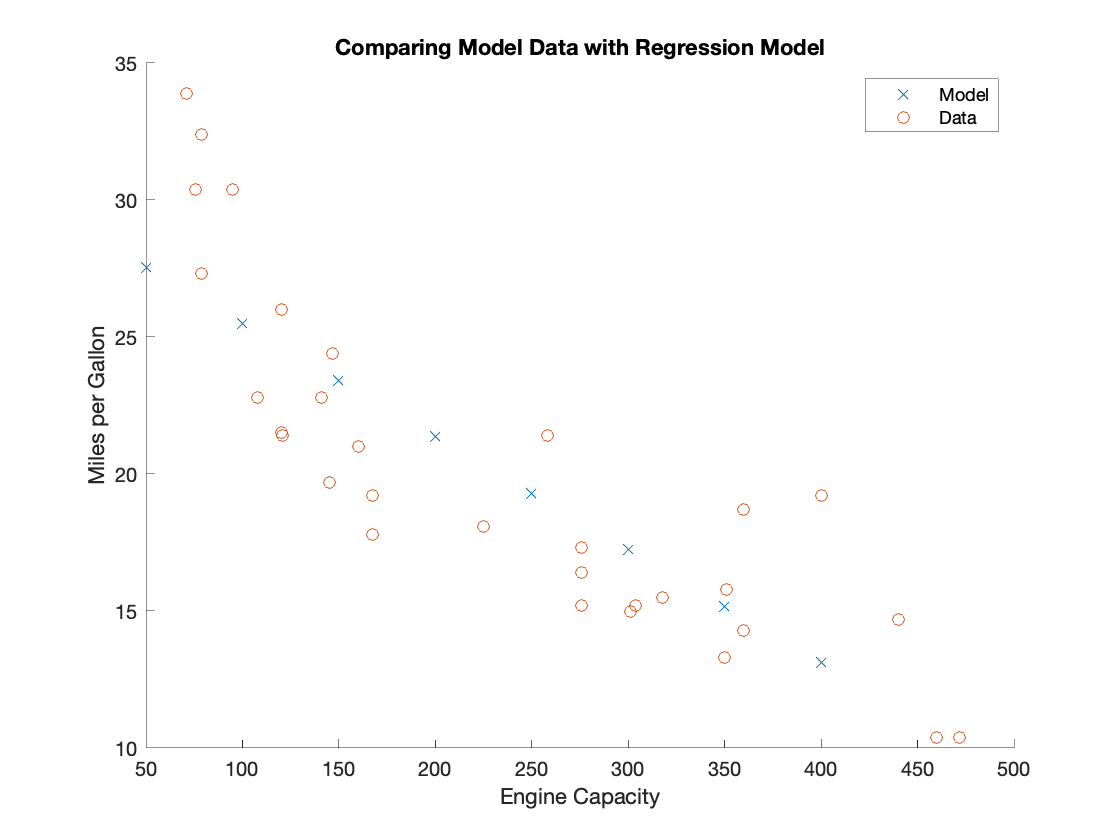

xtest=50:50:400;
ytest=b.*xtest+a;
figure
hold on
plot(xtest,ytest,'x');
plot(xv,yv,'o')
title('Comparing Model Data with Regression Model')
xlabel('Engine Capacity')
ylabel('Miles per Gallon')
legend('Model','Data')
hold off

# Classification Using Discriminant Analysis

Provided with a set of observational data, in the previous section we wanted to use our dataset  to generate a model and make a predictions of real values. Regression analysis is a technique we use to undertake such modelling.

For some data analytics, insight can be gained by investigating how data is organised. For example we may want a simple yes/no answer to a question. For example is this an image of a bird, does the text contain a reference to the President of The United States, is an Iris flower of versicolor or virginica? This is the problem of classification which many machine learning tools algorithms to solve. Here we examine the technique known as discriminant analysis to classify our motor vehicle data.

Discriminant analysis is a form of supervised learning in which the algorithm uses a set of examples or a training set to generalise all of the inputs other examples of supervised learning include decision trees and support vector machines. Unsupervised examples explore data using a statistical, gemetrical or similarity measure i.e. the training set is unlabelled. A good example is the k-means clustering algorithm.

Discriminant analysis is a classification method and assumes that different classes generate data based on different Gaussian distributions. To train (create) a classifier, the fitting function estimates the parameters of a Gaussian distribution for each class (see Creating Discriminant Analysis Model). To predict the classes of new data, the trained classifier finds the class with the smallest misclassification cost (see Prediction Using Discriminant Analysis Models). 

The classic example is  Fisher's sepal measurements for iris versicolor and virginica which were used to develop the technique known as discriminant analysis. An excellen example is provided in the matlab documentation:

[Discriminant Analysis Classification.](https://uk.mathworks.com/help/stats/discriminant-analysis.html)

Below, we use discriinant analysis to classify motor vehicles into high performance and high efficiency cars. The analysis follows a number of steps.

- Load data

- Use scatter diagrams to examine the distribution

- Generate a grid on the same scale and classify items across that grid

- Use a scatter diagram to visualise the classified data

- Use the coefficients generated by the classify function to compute and plot a decision boundary and visualise the classification

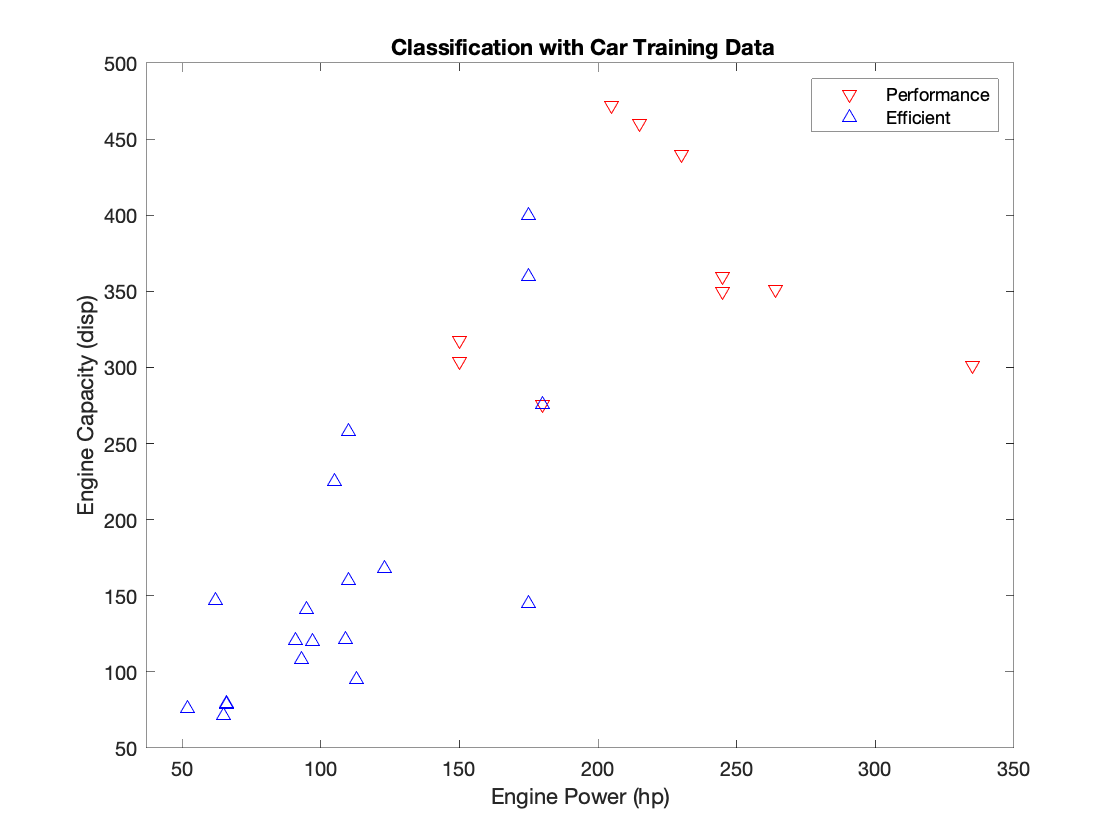

%Plot a scatter plot of our data -

data=readtable('../data/mtcars.csv');

hp=data.hp;
disp=data.disp;
group= (data.mpg > 17); %Use logical criteria to define the group


gscatter(hp,disp,group,'rb','v^',[],'off');
legend('Performance','Efficient')

xlabel('Engine Power (hp)')
ylabel('Engine Capacity (disp)')
title('{\bf Classification with Car Training Data}')

% Define the sample training set

[X,Y] = meshgrid(linspace(50,350,32),linspace(70,500,32));

X = X(:); Y = Y(:);

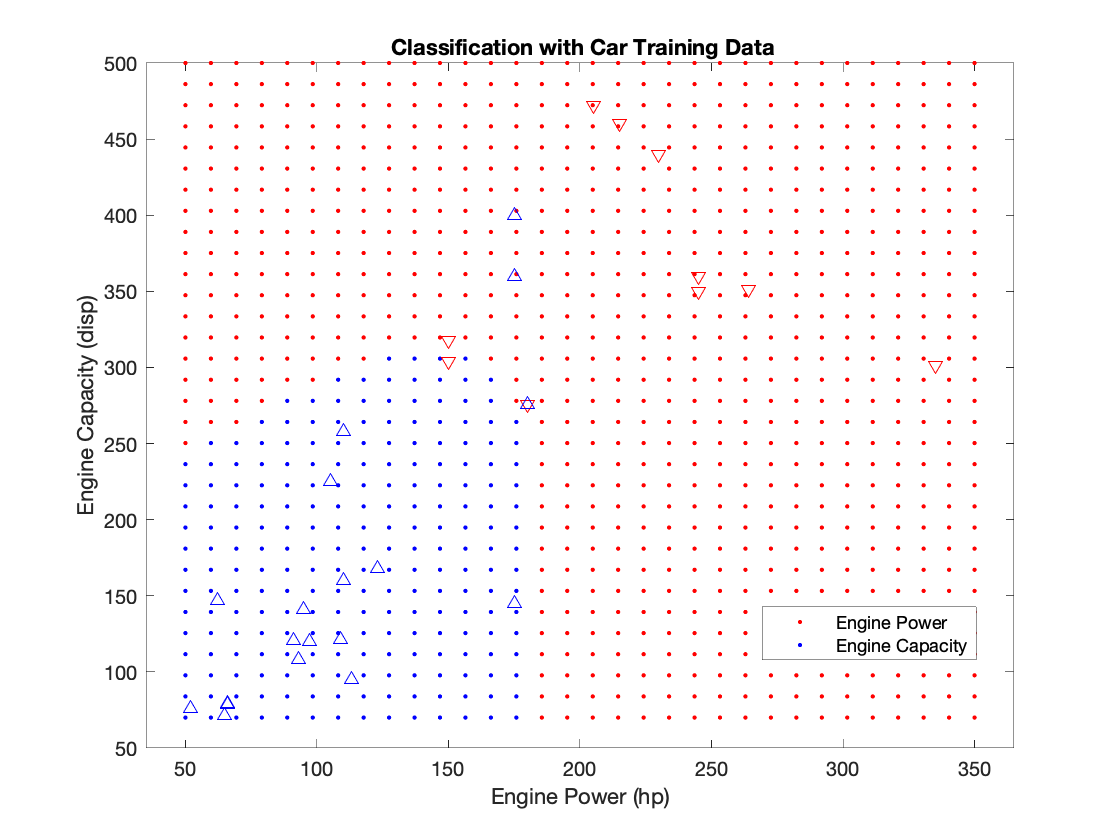


%[class,err,POSTERIOR,logp,coeff] = classify(sample,training,group,'type')

%Where 'type' can be :
%quadratic — Fits multivariate normal densities with covariance estimates stratified by group.
%other options are: linear, diaglinear, diagquadratic, mahalanobis

%The variable coeff is a structure array containing the coefficients of the boundary curves between pairs of groups.
%The variable C contains the group ID for each sample
[C,err,P,logp,coeff] = classify([X Y],[hp disp],...
                                group,'Quadratic');
                            
clf

gscatter(X,Y,C,'rb'); %display scatter pot of the sample

hold on
gscatter(hp,disp,group,'rb','v^',[],'off'); %scatter plot of the training set
legend('Engine Power','Engine Capacity')

xlabel('Engine Power (hp)')
ylabel('Engine Capacity (disp)')
title('{\bf Classification with Car Training Data}')

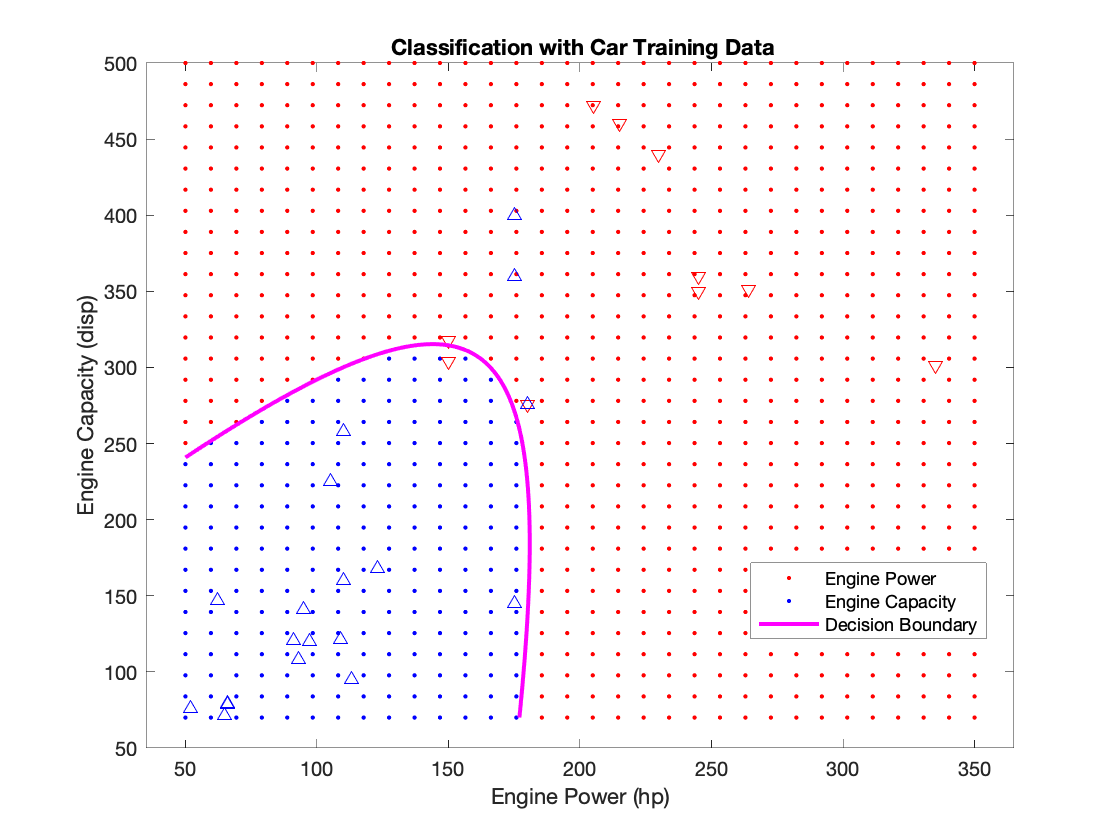


K = coeff(1,2).const;
L = coeff(1,2).linear; 
Q = coeff(1,2).quadratic;

% Function to compute K + L*v + v'*Q*v for multiple vectors
% v=[x;y]. Accepts x and y as scalars or column vectors.

%create a handle to an anonymous function
f = @(x,y) K + L(1)*x + L(2)*y + Q(1,1)*x.*x + (Q(1,2)+Q(2,1))*x.*y + Q(2,2)*y.*y;
h2 = fimplicit(f,[50 350 70 500]);

%Use the handle to the graphical primitive 
%to define the Colour, Line Width and to display a name
set(h2,'Color','m','LineWidth',2,'DisplayName','Decision Boundary')
hold off

# Processing Text

As a bonus example we consider a the processing of text data. We use data which has been read into text files. A range of tools is provided for importing text. We use the extractFileText function and can be used to read text from PDF, Microsoft Word, HTML, and plain text files.

In this example we read a series of text files and generate a word cloud.

%Read a list of text files
fileInfo = dir(['../data/soltext', filesep, '*.txt'])

fileInfo = 5×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


fileList = {fileInfo.name}

fileList = 1×5 cell array
    {'ASR_v1_resub1.txt'}    {'athena_GPU_murawski2013.txt'}    {'fluxtubes_roberts2001.txt'}    {'helioseismology_Christensen-Dalsgaard_2002.txt'}    {'magacousticwaveprop_localisedsolarfluxtube_fedun2011.txt'}



for k = numel(fileList):-1:1
    soltxt(k).FileName = fileList{k};
    soltxt(k).Data = fileread(['../data/soltext',filesep,fileList{k}]);
end


## Process the data

**Prepare Text Data for Analysis**

Create a function which tokenizes and preprocesses the text data so it can be used for analysis. The function `preprocessText`, listed at the end of the example, performs the following steps in order:

- Tokenize the text using `tokenizedDocument`.

- Lemmatize the words using `normalizeWords`.

- Erase punctuation using `erasePunctuation`.

- Remove a list of stop words (such as "and", "of", and "the") using `removeStopWords`.

- Remove words with 2 or fewer characters using `removeShortWords`.

- Remove words with 15 or more characters using `removeLongWords`.

Use the preprocessing function `preprocessText` to prepare the text data.

%documents = preprocessText(soltxt);

for i=1:5
    % Tokenize the text.
    documents = tokenizedDocument(soltxt(i).Data);
    
    % Lemmatize the words.
    documents = addPartOfSpeechDetails(documents);
    documents = normalizeWords(documents,'Style','lemma');
    
    % Erase punctuation.
    documents = erasePunctuation(documents);
    
    % Remove a list of stop words.
    documents = removeStopWords(documents);
    
    % Remove words with 2 or fewer characters, and words with 15 or greater
    % characters.
    documents = removeShortWords(documents,2);
    documents = removeLongWords(documents,15);
    
    alldocs(i)=documents;
end


Create a bag-of-words model from the tokenized documents.

for i=1:5
    bag(i) = bagOfWords(alldocs(i));

Remove words from the bag-of-words model that have do not appear more than two times in total. Remove any documents containing no words from the bag-of-words model. 

    bag(i) = removeInfrequentWords(bag(i),2);
    bag(i) = removeEmptyDocuments(bag(i));
end

Create a bag-of-words model from the tokenized documents.

bagall = bagOfWords(alldocs);

bagall =   bagOfWords with properties:

          Counts: [5×2211 double]
      Vocabulary: [1×2211 string]
        NumWords: 2211
    NumDocuments: 5


Remove words from the bag-of-words model that have do not appear more than two times in total. Remove any documents containing no words from the bag-of-words model. 

bagall = removeInfrequentWords(bagall,2);
bagall = removeEmptyDocuments(bagall)

## Visualize Topics Using Word Clouds

You can use word clouds to view the words with the highest probabilities in each topic. Visualize the first four topics using word clouds. 

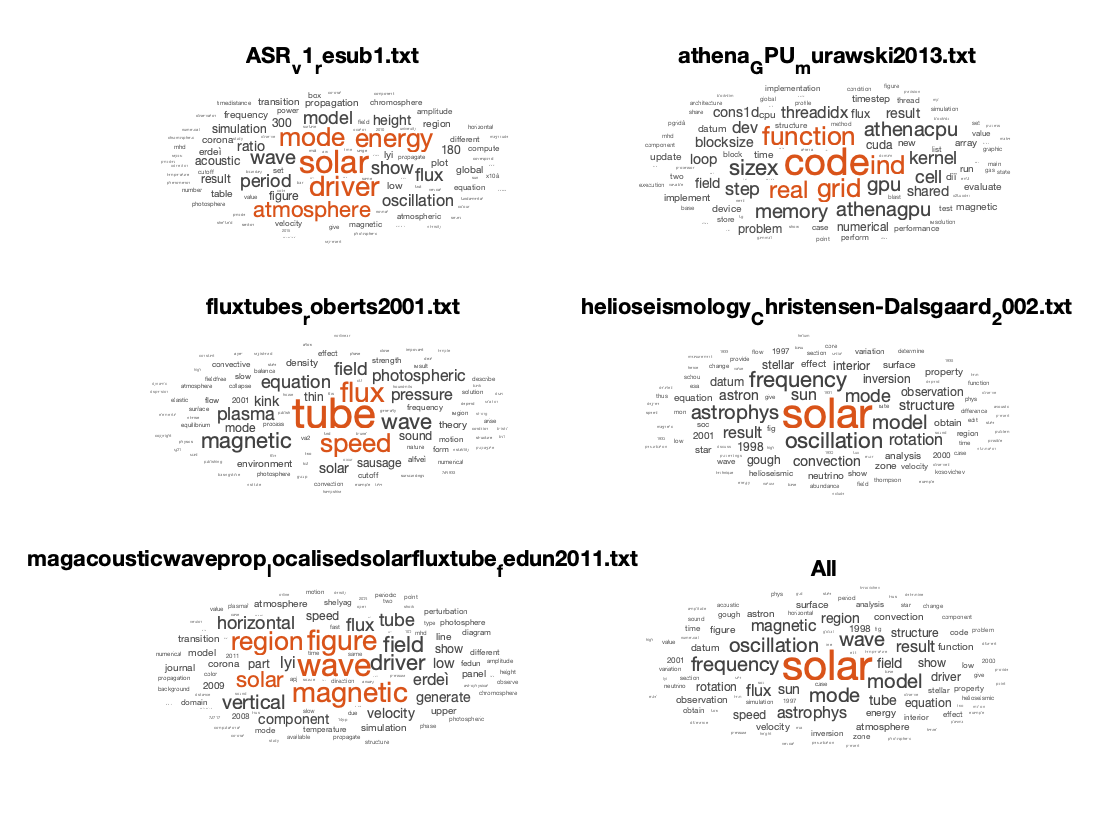

figure;
for topicIdx = 1:5
    subplot(3,2,topicIdx)

    wordcloud(bag(topicIdx));
    title(fileList{topicIdx})
end

subplot(3,2,6)
wordcloud(bagall);
title("All " )

The text for this example was generated from pdf files we used the pdftotext utility.

pdftotext can be installed using the poppler-utils package under various Linux distributions:

`For redhat linux variants`

`# yum install poppler-utils`

OR use the following under Debian / Ubuntu Linux

`$ sudo apt-get install poppler-utils`

pdftotext syntax

`pdftotext {``PDF-file``} {``text-file``}`